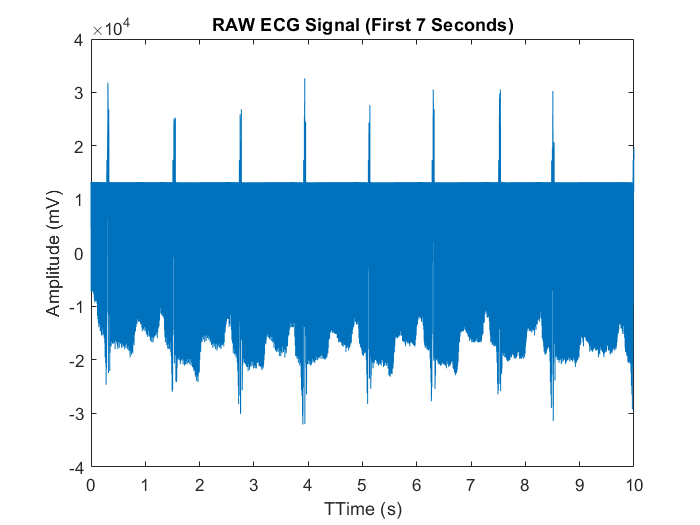

filename = '100.dat';
fid = fopen(filename, 'r');
ecg_signal = fread(fid, Inf, 'int16');
fclose(fid);

%Extract sampling frequency and time vector
fs = 360;
t = (0:length(ecg_signal)-1)/fs;

figure;
t_7sec = t(t<=10); %Adjust ime vector to only span first 7 seconds
plot(t_7sec, ecg_signal(1:length(t_7sec)));
xlabel('TTime (s)');
ylabel('Amplitude (mV)');
title('RAW ECG Signal (First 7 Seconds)');

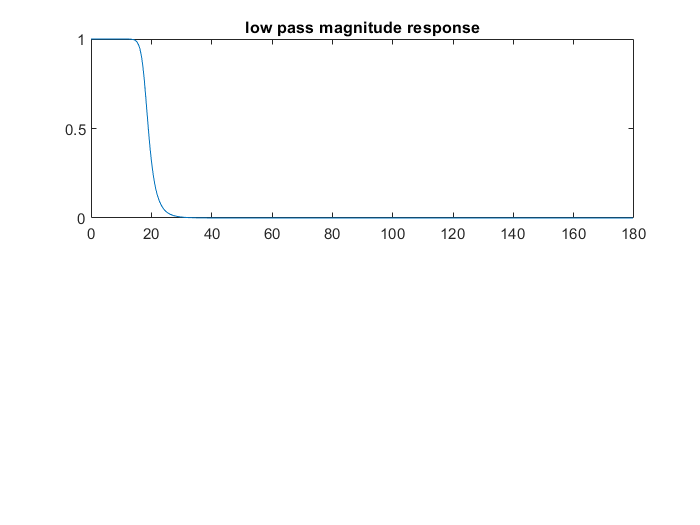

fs=360;
filter_order=10;
cuttoff_freq=18;
[b,a]= butter(filter_order, cuttoff_freq/(fs/2), 'low');
[h,w] = freqz(b,a);
figure(2)
subplot(2,1,1)
plot(w/pi*fs/2, abs(h), '-')
title ( 'low pass magnitude response')

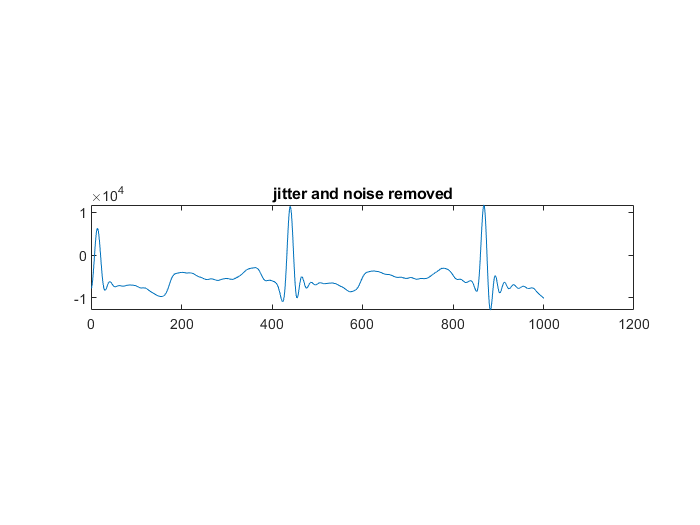

low_pass= filter(b,a,ecg_signal);
figure(3)
subplot(3,1,2)
plot(low_pass(1000:2000))
title('jitter and noise removed')

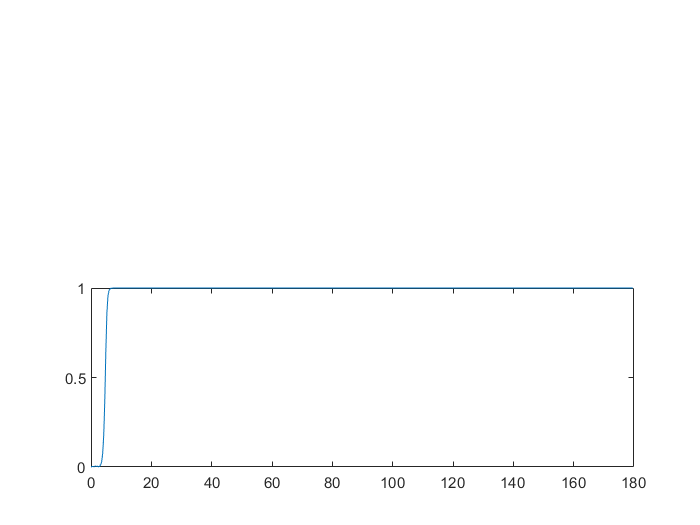

fs= 360;
filter_order=10;
cutoff_freq2= 5;
[b,a]= butter(filter_order, cutoff_freq2/(fs/2), 'high');
[h,w] = freqz(b,a);
figure(3)
subplot(2,1,2)
plot(w/pi*fs/2, abs(h), '-')

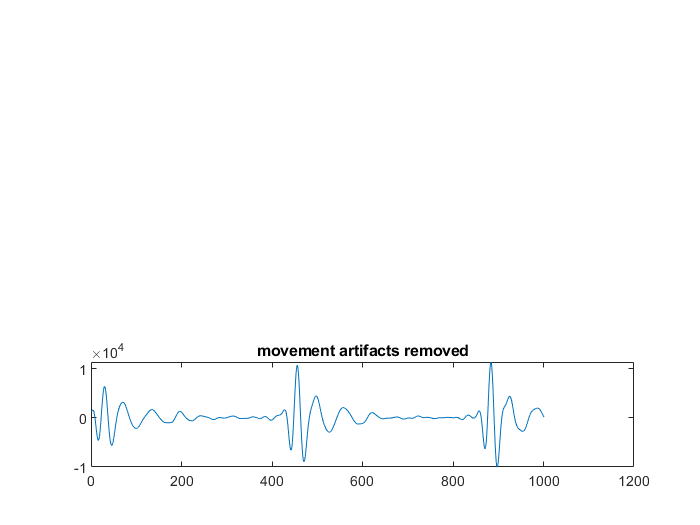


high_pass=filter(b,a,low_pass);
figure(4)
subplot(3,1,3)
plot(high_pass(1000:2000))
title('movement artifacts removed')

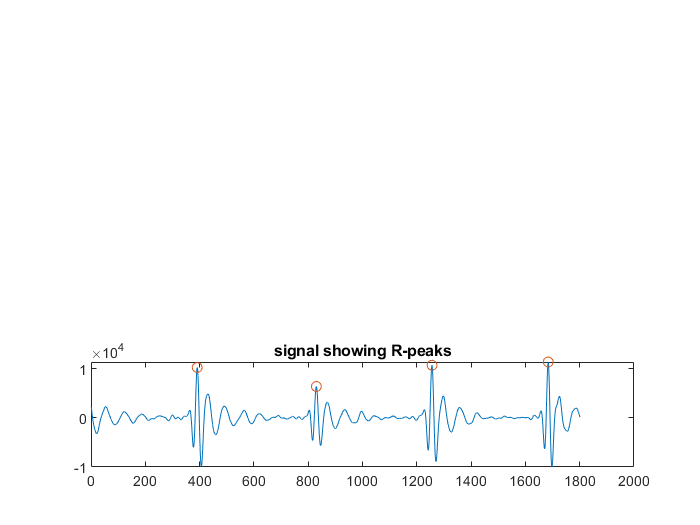

% Detect R-peaks for segmentation
[val, r_locs] = findpeaks(high_pass(200:2000), 'MinPeakHeight', 0.5*10^4);
plot(1:length(high_pass(200:2000)), high_pass(200:2000), r_locs, val, 'o')
title('signal showing R-peaks')


% Calculating NN intervals
nn_intervals = diff(r_locs) 

nn_intervals =    439
   426
   428



% Determination of RMSSD and SDNN 
rmssd = sqrt(mean(diff(nn_intervals).^2)); 
sdnn = std(nn_intervals); 
disp(['RMSSD: ', num2str(rmssd)]);

RMSSD: 9.3005


disp(['SDNN: ', num2str(sdnn)]);

SDNN: 7



% Number of beats in signal
num_beats = length(r_locs);
fprintf('Number of beats in signal: %d\n', num_beats);

Number of beats in signal: 4



% Heart rate
heart_rate = 60 ./ (mean(nn_intervals) / fs);
disp(['Heart Rate (BPM): ', num2str(heart_rate)]);

Heart Rate (BPM): 50.116


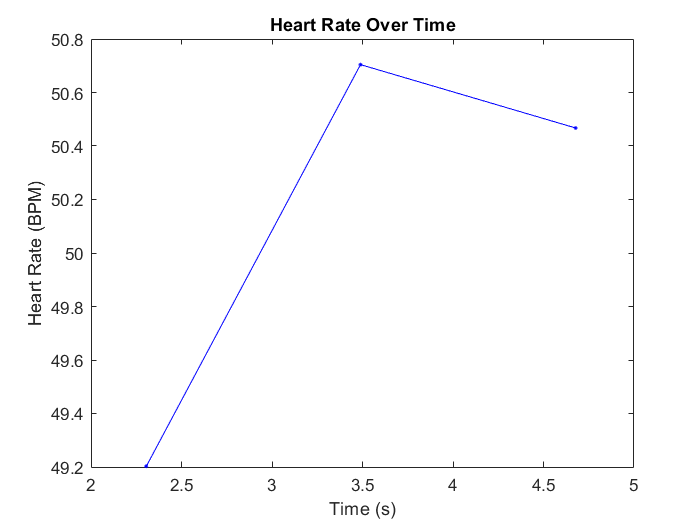


% Plot heart rate over time
t_hr = r_locs / fs;  % Time stamps corresponding to R-peaks
figure;
plot(t_hr(2:end), 60 ./ (nn_intervals / fs), 'b.-');  % Convert NN intervals to heart rate (BPM)
xlabel('Time (s)');
ylabel('Heart Rate (BPM)');
title('Heart Rate Over Time');

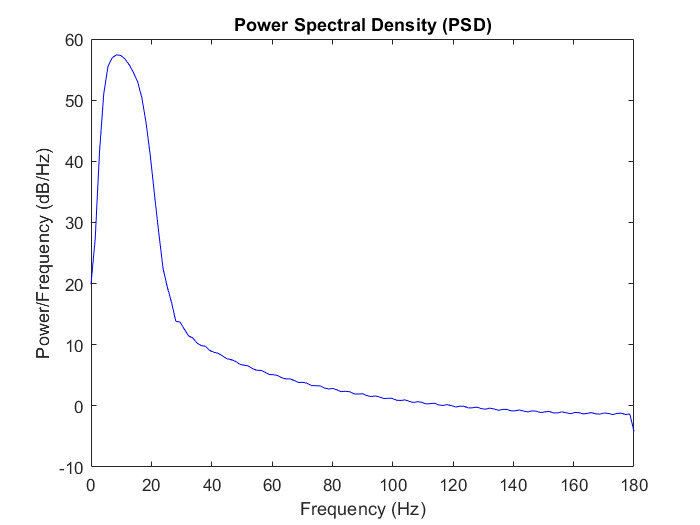


%power spectral density
win_length = round(0.5 * fs);  % Window length for PSD estimation (half-second window)
overlap = round(0.25 * fs);     % Overlap between consecutive windows
[psd, f] = pwelch(high_pass(200:2000), hamming(win_length), overlap, [], fs);

% Plot PSD
figure;
plot(f, 10*log10(psd), 'b');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
title('Power Spectral Density (PSD)');


% Check for rhythm disturbances based on threshold values
rmssd_threshold_low= 16; 
rmssd_threshold_high= 107

rmssd_threshold_high = 107

sdnn_threshold_high = 100;  
sdnn_threshold_low = 50

sdnn_threshold_low = 50


if rmssd < rmssd_threshold_low ||rmssd > rmssd_threshold_high|| sdnn < sdnn_threshold_low || sdnn> sdnn_threshold_high
    disp('Rhythm disturbance detected!');
else
    disp('No rhythm disturbance detected.');
end

Rhythm disturbance detected!


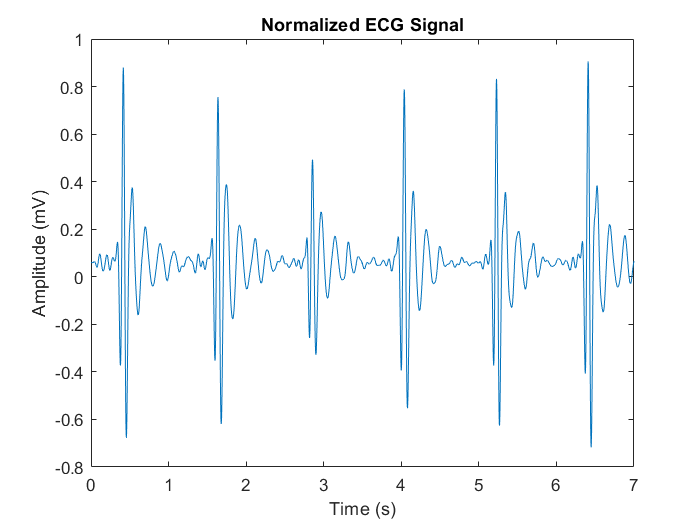

% Normalize amplitude of filtered ECG signal to range [-1, 1]
normalized_signal = (high_pass - min(high_pass)) / (max(high_pass) - min(high_pass)) * 2 - 1;


% Plot the normalized ECG signal
figure;
t_7sec = t(t<=7); % Adjust time vector to only span first 7 seconds
plot(t_7sec, normalized_signal(1:length(t_7sec)));
xlabel('Time (s)');
ylabel('Amplitude (mV)');
title('Normalized ECG Signal');